Load the Apple Watch dataset into the variable "data" using the Turbo drive path

temp = load('Toyota/Data/Processed/BigIdeasLab_HRSmartwatch/hrdata.mat');
data = temp.hrdata;

TASK 1: Create a simple histogram of the ECG heart rate versus Apple Watch heart rate. Plot ECG histogram first.

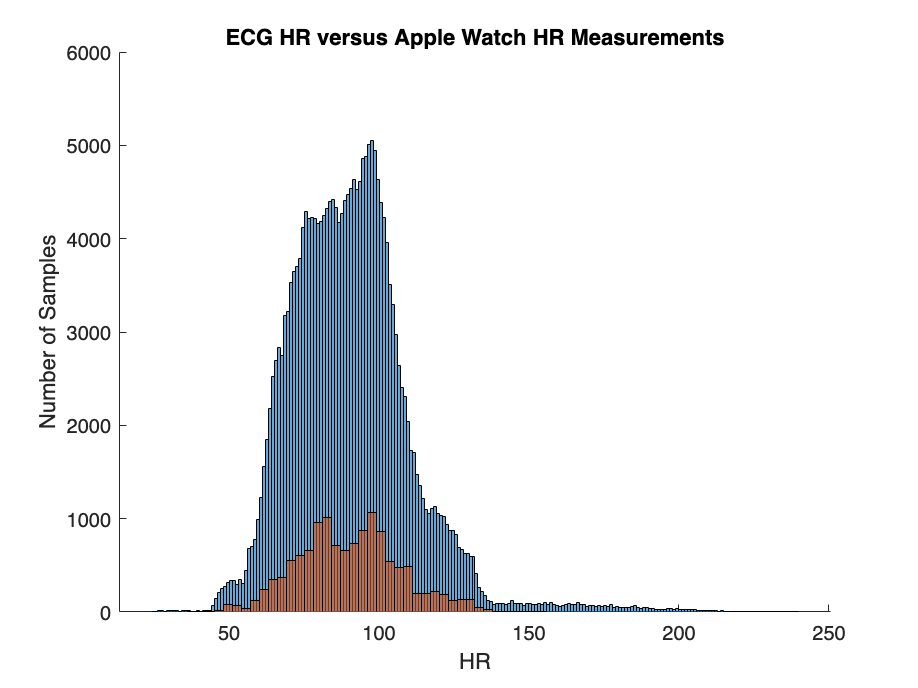

figure; hold on; % this lets you plot multiple histograms for comparison

% your code here

ecg_hr = table2array(data(:,1));
apple_hr = table2array(data(:,2));


histogram(ecg_hr);
histogram(apple_hr);



title('ECG HR versus Apple Watch HR Measurements')
xlabel('HR')
ylabel('Number of Samples')

TASK 2: Let's try removing some outliers from the ECG HR distribution to get a better view. Plot both histograms in the same figure after removing ECG outliers. (Hint: search for how to remove outliers in Matlab)

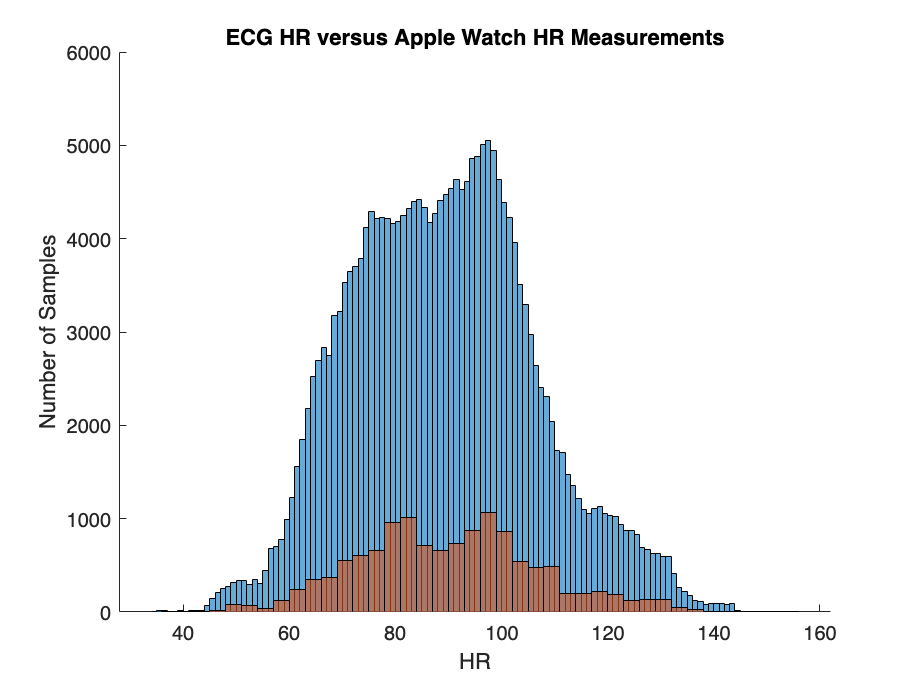

figure; hold on; % this lets you plot multiple histograms for comparison

% your code here
ecg_hr = table2array(data(:,1));
apple_hr = table2array(data(:,2));
ecg_hr_cleaned = ecg_hr(~isoutlier(ecg_hr));

histogram(ecg_hr_cleaned);
histogram(apple_hr);

title('ECG HR versus Apple Watch HR Measurements')
xlabel('HR')
ylabel('Number of Samples')

BONUS: Can you plot the same figure as above but make the histogram bins larger? (This will create a nicer looking figure to put on your poster).

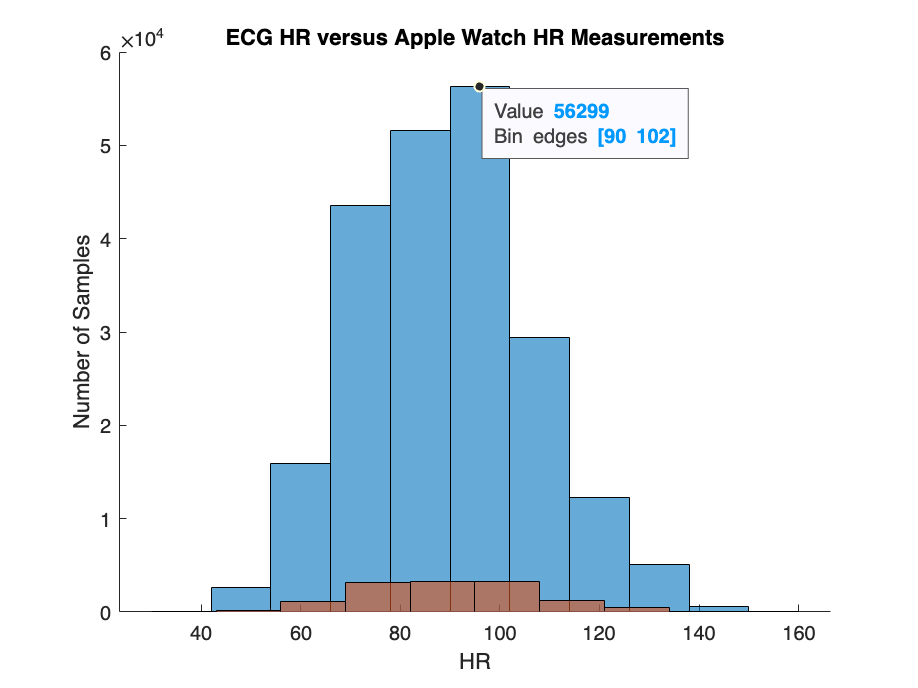

% your code here
figure; hold on;
histogram(ecg_hr_cleaned,10);

histogram(apple_hr,10);

title('ECG HR versus Apple Watch HR Measurements')
xlabel('HR')
ylabel('Number of Samples')

TASK 3: What do you notice about the two histograms? Do the distributions look the same? Is there one main "peak" in the distribution, or does it look more like a bimodal distribution?

[https://www.statology.org/bimodal-distribution/](https://www.statology.org/bimodal-distribution/)

Think about the dataset and how it was collected. What could have resulted in the heart rate distributions looking like this?

There is one main peak in ECG at around 90 HR, while AW has peaks from 70 to 110.

TASK 4: Let's calculate how much Apple Watch HR differs from ECG HR on average.

matched = data((~isnan(data.ECG) & ~isnan(data.AppleWatch)), :);
MDE = mean(matched.ECG - matched.AppleWatch);
MAE = mean(abs(matched.ECG - matched.AppleWatch));
disp(MDE)  % mean directional error

    0.3186



disp(MAE) % mean absolute error

    5.4191



How about over a range of ECG HR values?

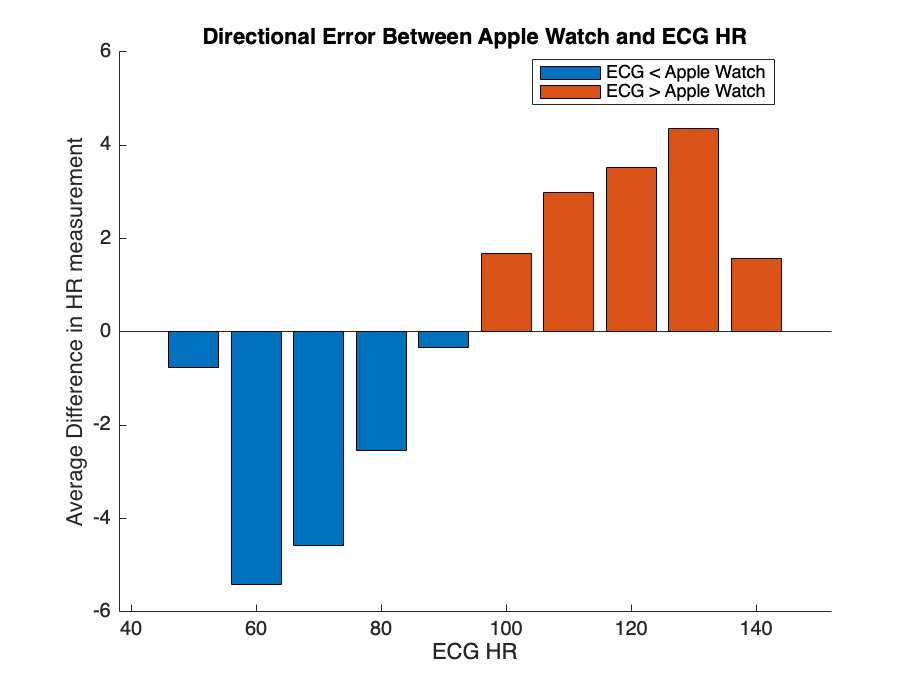

differences = matched.ECG - matched.AppleWatch;

% calculate average difference for every 10 HR range (for example, find
% average HR difference when ECG HR is within the range [70, 80)
% Plot the differences in a bar graph where the x-axis is ECG heart rate
% (separated into bins of size 10)
% and the y-axis is the average difference in HR value

edges = [40, 50, 60, 70, 80, 90, 100, 110, 120, 130, 140, 150];
avg_diffs = [];
for ei = 1:length(edges)-1
    leftedge = edges(ei);
    rightedge = edges(ei+1);
    % your code here
    idx = matched.ECG >= leftedge & matched.ECG < rightedge;
    avg_diffs(ei) = mean(differences(idx));
    
end

figure; hold on;
bar(edges(2:6), avg_diffs(1:5))
bar(edges(7:11), avg_diffs(6:10))
xlabel('ECG HR')
ylabel('Average Difference in HR measurement')
title('Directional Error Between Apple Watch and ECG HR')
legend('ECG < Apple Watch', 'ECG > Apple Watch', 'Location', 'best')

Do you notice a trend? Does the average difference between ECG and Apple Watch HR change when ECG HR is below 90 compared to above 90? What does this tell us about the Apple Watch HR measurements?

Plot the same graph but this time use Apple Watch HR as the x-axis.

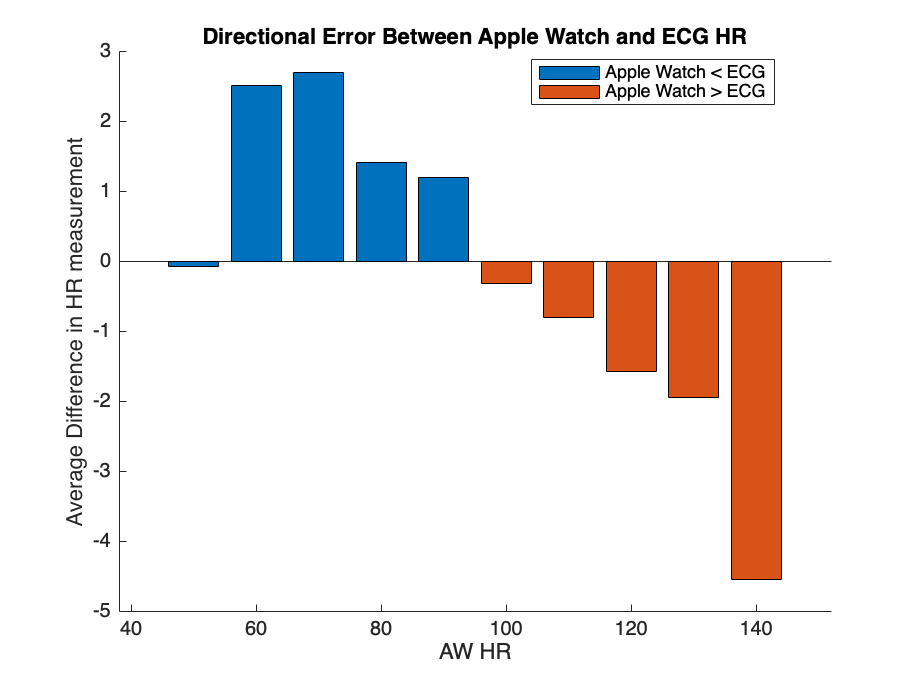

% calculate average difference for every 10 HR range (for example, find
% average HR difference when AW HR is within the range [70, 80)
% Plot the differences in a bar graph where the x-axis is ECG heart rate
% (separated into bins of size 10)
% and the y-axis is the average difference in HR value

edges = [40, 50, 60, 70, 80, 90, 100, 110, 120, 130, 140, 150];
avg_diffs = [];
for ei = 1:length(edges)-1
    leftedge = edges(ei);
    rightedge = edges(ei+1);
    % your code here
    range_indices = matched.AppleWatch >= leftedge & matched.AppleWatch < rightedge;
    range_diffs = differences(range_indices);
    avg_diff = mean(range_diffs);
    avg_diffs = [avg_diffs; avg_diff];
    
    
end

figure; hold on;
bar(edges(2:6), avg_diffs(1:5))
bar(edges(7:11), avg_diffs(6:10))
xlabel('AW HR')
ylabel('Average Difference in HR measurement')
title('Directional Error Between Apple Watch and ECG HR')
legend('Apple Watch < ECG', 'Apple Watch > ECG', 'Location', 'best')

TASK 5: Let's replot a scatterplot that colored by activity type from our analysis a couple weeks back.

We can also plot a line of best fit through the scattered points to see if the same trend shows up.

figure; hold on;
gscatter(matched.ECG, matched.AppleWatch, matched.Activity, 'rgbky', 'o*+xd', [10 10 10 10 10], 'on')
title('ECG versus Apple Watch HR colored by activity')
xlabel('ECG HR')
ylabel('Apple Watch HR')
legend('Location', 'best')
xlim('tight')

% remove outliers
[~, cleanidx] = rmoutliers(matched.ECG);
cleaned = matched;
cleaned(cleanidx,:) = [];

% use the variable "cleaned" to fit a line of best fit and plot it

% your code here

Does the line of best fit match the patterns seen in the bar plots you previously created?